usage: teamwork for week 8

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.4.25

clear all; close all; clc

**1.  已知连续函数**$$f(x)$$**在**$$x=-1,0,2,3$$**处的值分别是**$$-4,-1,0,3$$**，**

**   (1) 应用牛顿插值法中对差商得定义， 手算完成以下表格，     **

解：

| $ $x_i$$         | $$y_i$$          | 1st           | 2nd           | 3rd            |

| -1         | -4          |                 |                  |                  |

| 0          | -1          | 3              |                  |                  |

| 2          | 0           | 0.5           | -0.833333 |                  |

| 3          | 3           | 3              | 0.833333  | 0.416667  |

**(2) 修改样本文件`NewtonInterp.m`, 使之能够如下图格打印出以上表格内容， 并且核对以上手算结果是否正确？**

解：

clear all;
x_1 = [-1 0 2 3];
y_1 = [-4 -1 0 3];
display_NewtonInterp(x_1, y_1)

-1.000000		-4.000000		 0.000000		 0.000000		 0.000000		
 0.000000		-1.000000		 3.000000		 0.000000		 0.000000		
 2.000000		 0.000000		 0.500000		-0.833333		 0.000000		
 3.000000		 3.000000		 3.000000		 0.833333		 0.416667		


**(3) 编写若干行代码求得**$$f(1.5)$$**的近似值.**

解：

yi_1 = NewtonInterp(x_1, y_1, 1.5)

yi_1 = -0.4063

通过牛顿插值得到$f(1.5)=-0.4063$

**2. 请阅读[参考文献](https://blog.csdn.net/weixin_44586750/article/details/101544918)中关于埃特金插值部分(Aitken interpolation method). 埃特金插值方法最显著的两个特点是：**

**   - 不计算多项式插值中有关多项式的系数， 只是计算插值的结果， 因此埃特金表格上所有数值都是插值的结果。**

**   - 由此可以估算结果的收敛情况， 使得误差小于预先设置的误差.  **

**    (1) 测试实现埃特金插值方法的代码： 利用埃特金插值法重新求解习题1(3), 采用三阶多项式插值的结果是否相同？**

解：

clear all;
x_2_1 = [-1 0 2 3];
y_2_1 = [-4 -1 0 3];
[Q_2_1, R_2_1] = aitken(x_2_1, y_2_1, 1.5)

Q_2_1 =   -0.406250000000000


R_2_1 =   -1.000000000000000  -4.000000000000000                   0                   0                   0
                   0  -1.000000000000000   3.500000000000000                   0                   0
   2.000000000000000                   0  -0.666666666666667   0.375000000000000                   0
   3.000000000000000   3.000000000000000   0.375000000000000   1.937500000000000  -0.406250000000000


e_r_2_1 = Q_2_1 - NewtonInterp(x_2_1, y_2_1, 1.5);
fprintf("aitken三阶多项式插值与牛顿插值法的结果相差%f", e_r_2_1);

aitken三阶多项式插值与牛顿插值法的结果相差0.000000

因此得到aitken三阶多项式插值的结果和牛顿插值方法的结果是相同的。

**    (2) 产生一组函数**$$f(x)=x^{1.4}-\sqrt{x}+1/x-100$$**在`x=20:2:30`处的函数值。 利用埃特金插值法求解在**$$f(x)$$**在区间**$$[20,30]$$**上的根。**

解：首先产生$f(x)$在`x=20:2:30`上的函数值，假定我们没有$f(x)$的函数表达式，只有离散的数据点。

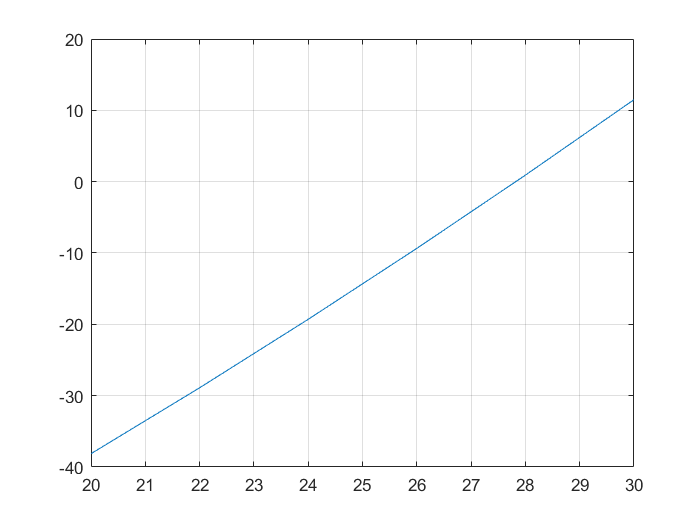

f_2_2 = @(x) x.^(1.4) - sqrt(x) + 1./x - 100;
x_2_2 = 20:2:30;
y_2_2 = f_2_2(x_2_2);
plot(x_2_2, y_2_2)
grid on

从图像上可以得到根在区间$[27, 28]$间，

format long
[answer_2_2, order_2_2] = root_by_aitken(x_2_2, y_2_2, 1e-6)

root_by_aitken:
the root of f(x) = 0, is x = 27.823484, the fitting polynomial order is 4

answer_2_2 =   27.823484280957871


order_2_2 =      4


answer_2_2_lxy = fzero(@(x) aitken(x_2_2, y_2_2, x), [27, 28])

answer_2_2_lxy =   27.823484280957871


check_2_2 = fzero(f_2_2, [20, 30])

check_2_2 =   27.823484209740315


从结果可以得到通过埃特金插值方法求得的解$x\approx27.823484$与通过原函数进行fzero得到的结果在误差范围内基本相等。

[answer_2_2, order_2_2] = root_by_aitken(x_2_2, y_2_2, 1e-7);

root_by_aitken:
拟合数据无法达到1.000000e-07的精度

但事实上由于拟合数据本身的精度的限制，求得的零点无法小于$10^{-7}$的量级。

**3. 判断下列哪些函数是否是三次样条？**


$$$$
  \begin{array}{ll}
  (1) & f(x)=\begin{cases}
  \frac{19}{2}-\frac{81}{4}x+15x^2-\frac{13}{4}x^3, & 1\leq x\leq 2\\
  -\frac{77}{2}+\frac{207}{4}x-21x^2+\frac{11}{4}x^3, & 2\leq x \leq 3
  \end{cases}\\
  (2) & f(x)=\begin{cases}
  11-24x+18x^2-{4}x^3, & 1\leq x\leq 2\\
  -54+72x-30x^2+4x^3, & 2\leq x \leq 3
  \end{cases}\\
  (3) & f(x)=\begin{cases}
  13-31x+23x^2-5x^3, & 1\leq x\leq 2\\
  -35+51x-22x^2+3x^3, & 2\leq x \leq 3
  \end{cases}\\
  \end{array}
  $$$$


解：

（1）

clear all;
f_3_1_1 = @(x) 19/2 - 81/4*x + 15*x^2 - 13/4*x^3;
f_3_1_2 = @(x) -77/2 + 207/4*x - 21*x^2 + 11/4*x^3;
X_3_1 = 2;
fprintf("第一个")

第一个

flag_3_1 = Cubic_Spline_Interpolation({f_3_1_1, f_3_1_2}, X_3_1);

是三次样条函数

第一个是三次样条。

（2）

f_3_2_1 = @(x) 11 - 24*x + 18*x^2 - 4*x^3;
f_3_2_2 = @(x) -54 + 72*x - 30*x^2 + 4*x^3;
X_3_2 = 2;
fprintf("第二个")

第二个

flag_3_1 = Cubic_Spline_Interpolation({f_3_2_1, f_3_2_2}, X_3_2);

不是三次样条函数

第二个不是三次样条。

（3）

f_3_3_1 = @(x) 13 - 31*x + 23*x^2 - 5*x^3;
f_3_3_2 = @(x) -35 + 51*x - 22*x^2 + 3*x^3;
X_3_3 = 2;
fprintf("第三个")

第三个

flag_3_1 = Cubic_Spline_Interpolation({f_3_3_1, f_3_3_2}, X_3_3);

不是三次样条函数

第三个不是三次样条。

**4. 用**$$f(x)=1/(1+x^2)$$**产生一组数据**$$x=-2，-1，0，1，2$$**.  **

**   (1) 求解紧压三次样条， 其中**$$p =0.1$$**, **$$q=-0.1$$**，参考讲义，给出求解参数**$$a_i, b_i,c_i,d_i$$**的过程和结果。**

**   (2) 根据(1)的结果求**$$x =1.5$$**处的插值， 并与理论值比较。  **

**   (3) 如果**$$p =0.2$$**, **$$q=-0.2$$**， 结果会有什么不同?**

解：

（1）

clear all;
format short
f_4 = @(x) 1./(1+x.^2);
x_4 = [-2 -1 0 1 2]

x_4 =     -2    -1     0     1     2


y_4 = f_4(x_4)

y_4 =     0.2000    0.5000    1.0000    0.5000    0.2000



$$d_1=0.2,d_2=0.5,d_3=1.0,d_4=0.5,d_5=0.2$$



$$h_1=h_2=h_3=h_4=1.0$$



$$(2b_1+b_2)h_1=\frac{3(d_2-d_1)}{h_1}-3p\\
b_1h_1+2b_2(h_2+h_1)+b_3h_2=\frac{3(d_3-d_2)}{h_2}-\frac{3(d_2-d_1)}{h_1}\\

b_2h_2+2b_3(h_3+h_2)+b_4h_3=\frac{3(d_4-d_3)}{h_3}-\frac{3(d_3-d_2)}{h_2}\\

b_3h_3+2b_4(h_4+h_3)+b_5h_4=\frac{3(d_5-d_4)}{h_4}-\frac{3(d_4-d_3)}{h_3}\\
(2b_5+b_4)h_4=-\frac{3(d_5-d_4)}{h_4}+3q$$



$$\therefore \pmatrix{2.0 & 1.0 & 0 & 0 & 0
\cr 1.0 & 4.0 & 1.0 & 0 & 0
\cr 0 & 1.0 & 4.0 & 1.0 & 0
\cr 0 & 0 & 1.0 & 4.0 & 1.0
\cr 0 & 0 & 0 & 1.0 & 2.0}
\pmatrix{b_1 \cr b_2 \cr b_3 \cr b_4 \cr b_5}
=
\pmatrix{0.6 \cr 0.6 \cr -3 \cr 0.6 \cr 0.6}$$


A = [2 1 0 0 0; 1 4 1 0 0; 0 1 4 1 0; 0 0 1 4 1; 0 0 0 1 2];
B = [0.6; 0.6; -3; 0.6; 0.6];
b = A \ B

b =     0.1250
    0.3500
   -0.9250
    0.3500
    0.1250



$$\pmatrix{b_1 \cr b_2 \cr b_3 \cr b_4 \cr b_5}
=
\pmatrix{0.1250 \cr 0.3500 \cr -0.9250 \cr 0.3500 \cr 0.1250}$$



$$a_1=\frac{b_2-b_1}{3h_1}=0.0750\\
a_2=\frac{b_3-b_2}{3h_2}=-0.4250\\
a_3=\frac{b_4-b_3}{3h_3}=0.4250\\
a_4=\frac{b_5-b_5}{3h_4}=-0.0750$$
         
$$c_1=\frac{d_2-d_1}{h_1}-\frac13(2b_1+b_2)h_1=0.1\\
c_2=\frac{d_3-d_2}{h_2}-\frac13(2b_2+b_3)h_2=0.575\\
c_3=\frac{d_4-d_3}{h_3}-\frac13(2b_3+b_4)h_3=0\\
c_4=\frac{d_5-d_4}{h_4}-\frac13(2b_4+b_5)h_4=-0.575$$



$$\therefore\\
S_1=0.075(x+2)^3+0.125(x+2)^2+0.1(x+2)+0.2,-2\le x\le-1\\
S_2=-0.425(x+1)^3+0.35(x+1)^2+0.575(x+1)+0.5,-1\le x\le0\\
S_3=0.425x^3-0.925x^2+1, 0\le x \le 1\\
S_4=-0.075(x-1)^3+0.35(x-1)^2-0.575(x-1)+0.5,1\le x \le 2$$


运用CSFit进行验证：

cof = CSFit(x_4, y_4, 0.1, -0.1)

cof =     0.0750    0.1250    0.1000    0.2000
   -0.4250    0.3500    0.5750    0.5000
    0.4250   -0.9250         0    1.0000
   -0.0750    0.3500   -0.5750    0.5000


结果一致。

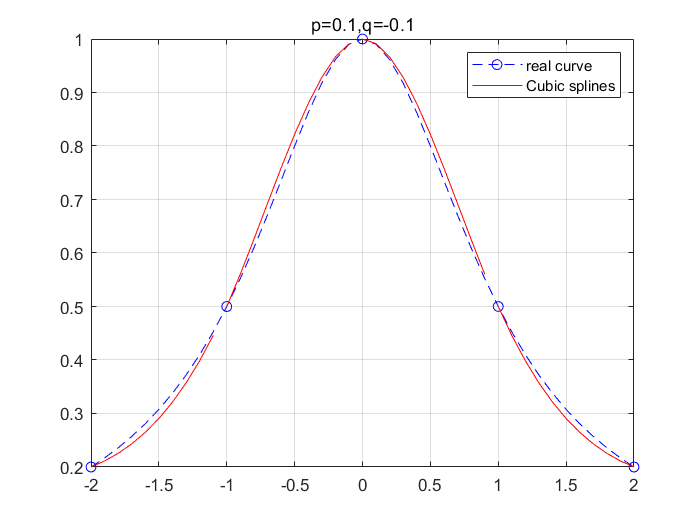

S_4_1_1 = @(x) 0.075.*(x+2).^3 + 0.125.*(x+2).^2 + 0.1.*(x+2) + 0.2;
S_4_1_2 = @(x) -0.425.*(x+1).^3 + 0.35.*(x+1).^2 + 0.575.*(x+1) + 0.5;
S_4_1_3 = @(x) 0.425.*x.^3 + -0.925.*x.^2 + 1;
S_4_1_4 = @(x) -0.075.*(x-1).^3 + 0.35.*(x-1).^2 - 0.575.*(x-1) + 0.5;
sample_4 = -2:0.1:2;
plot(sample_4, f_4(sample_4), 'b--o', 'MarkerIndices', 1:10:length(sample_4), 'DisplayName','real curve');
hold on
plot(sample_4(1:10), S_4_1_1(sample_4(1:10)), 'r', 'HandleVisibility','off');
plot(sample_4(11:20), S_4_1_2(sample_4(11:20)), 'r', 'HandleVisibility','off');
plot(sample_4(21:30), S_4_1_3(sample_4(21:30)), 'r', 'HandleVisibility','off');
plot(sample_4(31:41), S_4_1_4(sample_4(31:41)), 'r', 'DisplayName', 'Cubic splines');
hold off
title("p=0.1,q=-0.1");
grid on
legend

如图所示即为一阶导数的边界条件为$p=0.1,q=-0.1$的三次紧压样条与原函数的图像。

（2）

x_4_2 = 1.5;
Cubic_Spline_4_2_1 = S_4_1_4(x_4_2);
y_4_2 = f_4(x_4_2);
e_r_4_2 = (Cubic_Spline_4_2_1 - y_4_2) / y_4_2;
fprintf("x=1.5处的插值为%f, 理论值为%f, 两者相对误差为%e", Cubic_Spline_4_2_1, y_4_2, e_r_4_2)

x=1.5处的插值为0.290625, 理论值为0.307692, 两者相对误差为-5.546875e-02

（3）当一阶导数的边界条件为$p=0.2, q=-0.2$时

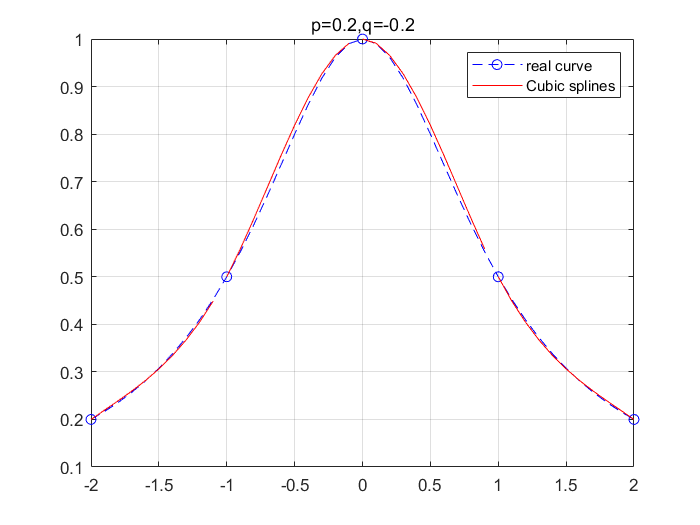

S_4_2 = CSFit(x_4, y_4, 0.2, -0.2);
S_4_2_1 = @(x) S_4_2(1,1).*(x+2).^3 + S_4_2(1,2).*(x+2).^2 + S_4_2(1,3).*(x+2) + S_4_2(1,4);
S_4_2_2 = @(x) S_4_2(2,1).*(x+1).^3 + S_4_2(2,2).*(x+1).^2 + S_4_2(2,3).*(x+1) + S_4_2(2,4);
S_4_2_3 = @(x) S_4_2(3,1).*x.^3 + S_4_2(3,2).*x.^2 + S_4_2(3,3).*x + S_4_2(3,4);
S_4_2_4 = @(x) S_4_2(4,1).*(x-1).^3 + S_4_2(4,2).*(x-1).^2 + S_4_2(4,3).*(x-1) + S_4_2(4,4);
sample_4 = -2:0.1:2;
plot(sample_4, f_4(sample_4), 'b--o', 'MarkerIndices', 1:10:length(sample_4), 'DisplayName','real curve');
hold on
plot(sample_4(1:10), S_4_2_1(sample_4(1:10)), 'r', 'HandleVisibility','off');
plot(sample_4(11:20), S_4_2_2(sample_4(11:20)), 'r', 'HandleVisibility','off');
plot(sample_4(21:30), S_4_2_3(sample_4(21:30)), 'r', 'HandleVisibility','off');
plot(sample_4(31:41), S_4_2_4(sample_4(31:41)), 'r', 'DisplayName', 'Cubic splines');
hold off
title("p=0.2,q=-0.2");
grid on
legend

可以看出边界条件为$p=0.2, q=-0.2$时在区间$[-2, -1]$和$[1, 2]$的拟合效果比$p=0.1,q=-0.1$更好。

Cubic_Spline_4_2_2 = S_4_2_4(x_4_2);
e_r_4_2 = (Cubic_Spline_4_2_2 - y_4_2) / y_4_2;
fprintf("x=1.5处的插值为%f, 理论值为%f, 两者相对误差为%e", Cubic_Spline_4_2_2, y_4_2, e_r_4_2)

x=1.5处的插值为0.306250, 理论值为0.307692, 两者相对误差为-4.687500e-03

边界条件为$p=0.2, q=-0.2$时，$f(1.5)$与理论值间的相对误差比$p=0.1,q=-0.1$小了一个数量级，拟合效果更好。

**5. 用**$$f(x)=\sin^2(\pi x/2)$$**产生一组数据`x=-1:0.2:1`. **

**   (1) 使用Matlab内置的多项式拟合函数`polyfit`对数据进行二次和四次多项式拟合， 请图示你的结果.**

**   (2) 使用Matlab内置的三次样条插值函数`spline`对数据插值计算， 请图示你的结果并与(1)比较。**

解：

（1）

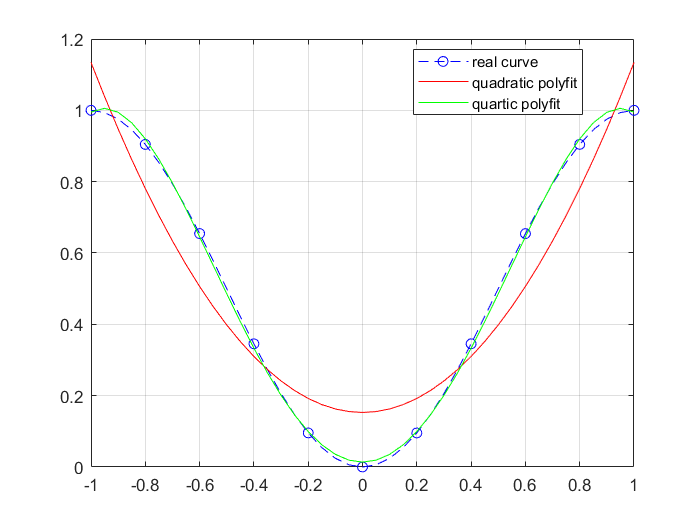

clear all
f_5 = @(x) sin(pi.*x/2).^2;
x_5 = -1:0.2:1;
y_5 = f_5(x_5);
%polyfit
quadratic_polyfit = polyfit(x_5, y_5, 2); % 二次
quartic_polyfit = polyfit(x_5, y_5, 4); % 四次
sample_5 = -1:0.05:1;
plot(sample_5, f_5(sample_5), 'b--o', 'MarkerIndices', 1:4:length(sample_5));
hold on
plot(sample_5, polyval(quadratic_polyfit, sample_5), 'r');
plot(sample_5, polyval(quartic_polyfit, sample_5), 'g');
hold off
grid on 
legend('real curve', 'quadratic polyfit', 'quartic polyfit','Location', 'best');

（2）

plot(sample_5, f_5(sample_5), 'b--o', 'MarkerIndices', 1:4:length(sample_5));
hold on
%spline
p_5 = spline(x_5, y_5);
c_5 = p_5.coefs;

c_5 =     1.8472   -3.0396    0.0566    1.0000
    1.8472   -1.9314   -0.9376    0.9045
    2.7007   -0.8231   -1.4885    0.6545
    2.1044    0.7973   -1.4936    0.3455
    0.8183    2.0600   -0.9222    0.0955
   -0.8183    2.5510    0.0000         0
   -2.1044    2.0600    0.9222    0.0955
   -2.7007    0.7973    1.4936    0.3455
   -1.8472   -0.8231    1.4885    0.6545
   -1.8472   -1.9314    0.9376    0.9045


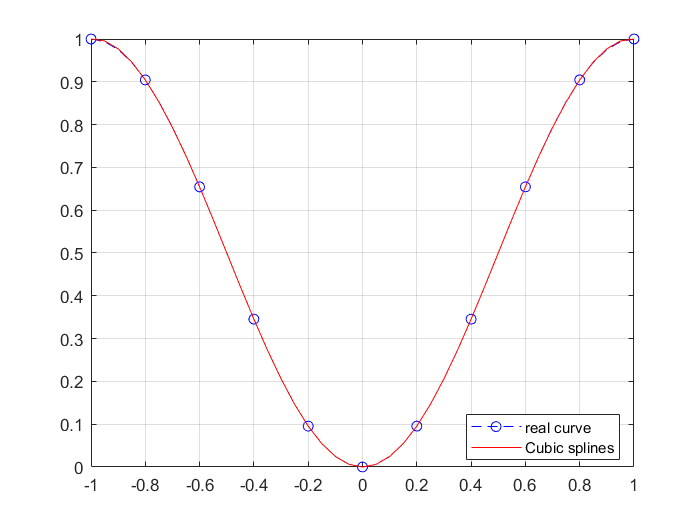

n_5 = length(x_5) - 1; % 样条函数的数量
for k = 1:n_5
    if k ~= n_5
        plot(sample_5(4*k-3:4*k+1), polyval(c_5(k,:), (sample_5(4*k-3:4*k+1) - x_5(k))), 'r', 'HandleVisibility','off');
    else
        plot(sample_5(4*k-3:4*k+1), polyval(c_5(k,:), (sample_5(4*k-3:4*k+1)) - x_5(k)), 'r');
    end
end
hold off
grid on
legend('real curve', 'Cubic splines', 'Location', 'best');

三种方法相比较，二次多项式polyfit拟合的效果最差，四次多项式polyfit拟合后仍有部分曲线与原函数曲线相重合，而三次样条插值函数‘spline’得到的曲线基本和原函数完全重合，拟合效果最好。

**6. 输入以下代码**

'figure('position',get(0,'screensize'))

axes('position',[0 0 1 1])

[x,y] = ginput;'

**你把手放在屏幕上， 通过鼠标在五个手指边缘取若干个点获得坐标， 打入==Enter==终止。 你也可以设计其他方法取点。 **

**   (1) 将你的数据存储至文件。**

**   (2) 从该文件读出数据， 使用分段三阶多项式插值画出你的手， 你的结果应当相似下图。请分别采用Matlab内置函数`spline`和`pchip`计算并比较结果。**

解：

（2）

黄哲昊：

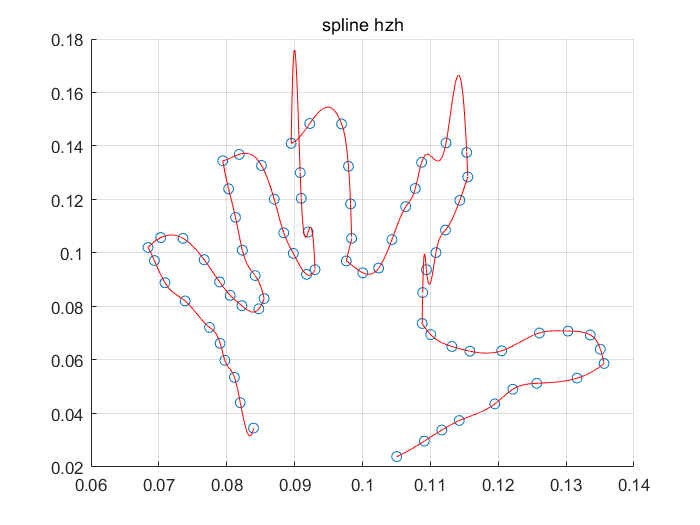

clear all; close all; clc
format long
% 从hand.mat文件中读出数据
load('hand_hzh.mat', 'x_6', 'y_6');
scatter(x_6, y_6)
hand_spline(x_6', y_6', 'hzh')

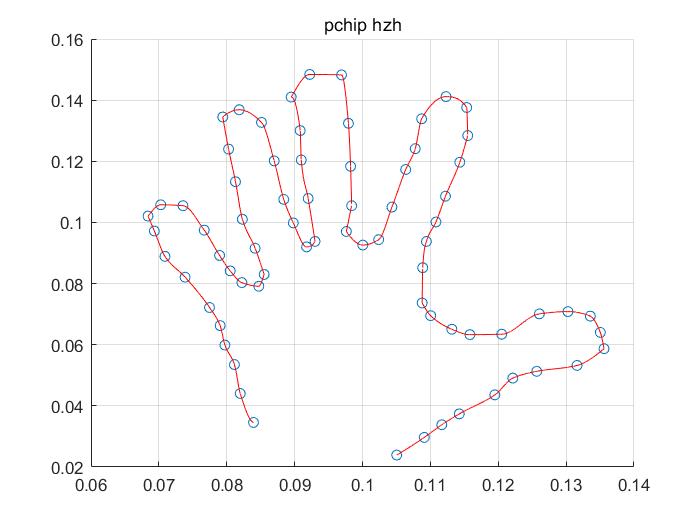

clear all;close all; clc
format long
% 从hand.mat文件中读出数据
load('hand_hzh.mat', 'x_6', 'y_6');
scatter(x_6, y_6)
hand_pchip(x_6', y_6', 'hzh')

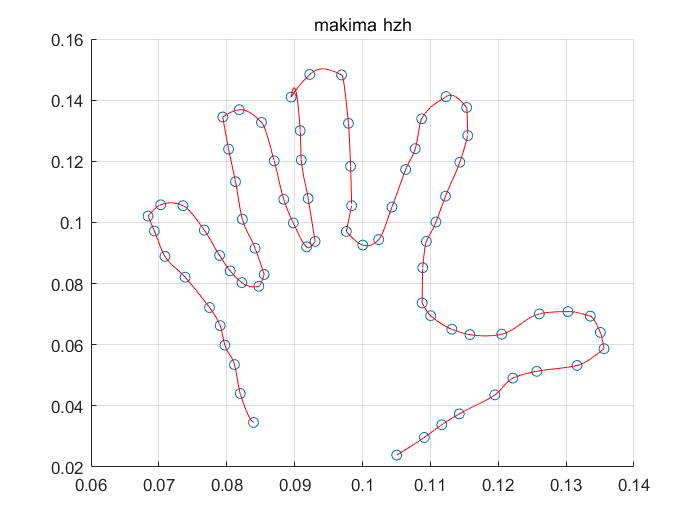

clear all;close all; clc
format long
% 从hand.mat文件中读出数据
load('hand_hzh.mat', 'x_6', 'y_6');
scatter(x_6, y_6)
hand_makima(x_6', y_6', 'hzh')

毛晨光：

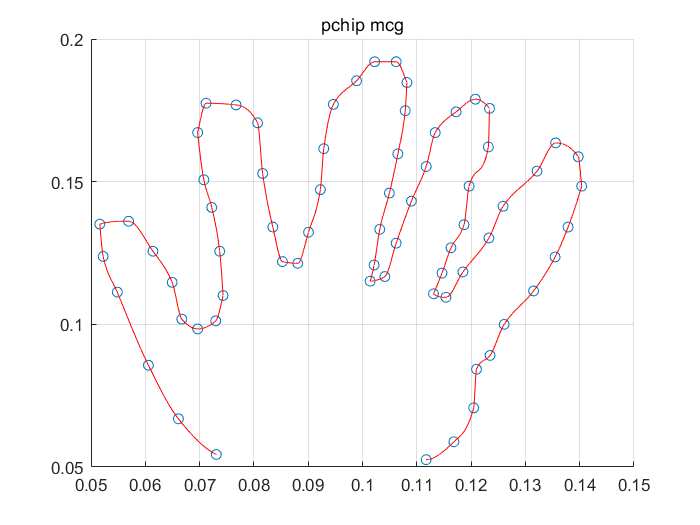

clear all;close all; clc
format long
% 从hand.mat文件中读出数据
load('hand_mcg.mat', 'x_6', 'y_6');
scatter(x_6, y_6)
hand_pchip(x_6', y_6', 'mcg')

鲁潇阳：

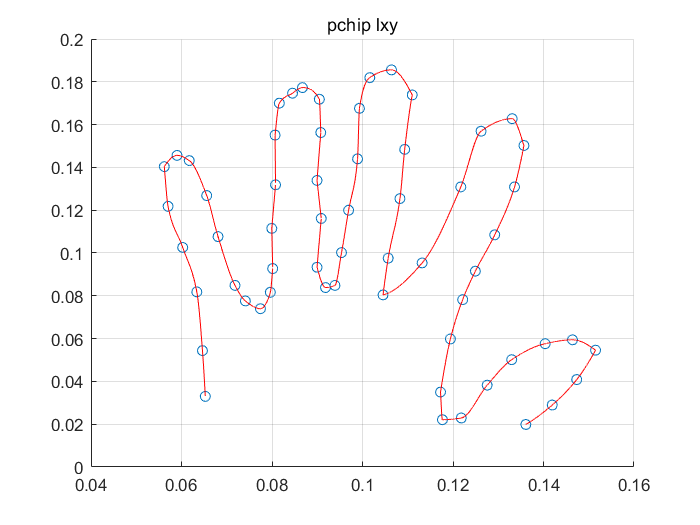

clear all;close all; clc
format long
% 从hand.mat文件中读出数据
load('hand_lxy.mat', 'x_6', 'y_6');
scatter(x_6, y_6)
hand_pchip(x_6', y_6', 'lxy')

************************************************functions************************************************************

display_NewtonInterp：将牛顿插值法计算时的差商表格进行打印

args：

    x：插值的自变量，行向量；

    y：插值的应变量，行向量；

output：

    无，只是将表格进行打印。

function display_NewtonInterp(x, y)
    n = length(x) - 1;
    D = zeros(n+1, n+2);
    D(:, 1) = x';
    D(:, 2) = y';
    
    for j = 3:n+2
        for k = j-1:n+1
            D(k, j) = (D(k, j-1) - D(k-1, j-1))/(D(k, 1) - D(k-j+2, 1));
        end
    end
    
    for i = 1:n+1
        for j = 1:n+2
            if D(i, j) >= 0 
                fprintf(" %f\t\t", D(i, j));
            else
                fprintf("%f\t\t", D(i, j));
            end
        end
        fprintf("\n");
    end
    
end

NewtonInterp：运用牛顿插值法计算插值

args：

    x：拟合数据的自变量，行向量；

    y：拟合数据的应变量，行向量；

    xi：进行插值的自变量

output：

    yi：插值的结果

function yi = NewtonInterp(x,y,xi)
    n = length(x)-1;
    D = zeros(n+1,n+1); % Pre-allocate  of divided-differences
    D(:,1) = y';
    
    for j = 2:n+1
        for k = j:n+1
            D(k,j) = (D(k,j-1) - D(k-1,j-1))/(x(k) - x(k-j+1));
        end
    end

    yi = 0;
    for j = n+1:-1:1
        p = D(j,j);
        for k = 1:j-1
            p = p*(xi - x(k)); 
        end
        yi = yi + p;
    end
end

aitken：埃特金插值方法

args：

    x：拟合数据的自变量

    y：拟合数据的应变量

    xval：需要插值的自变量

output：

    Q：是插值得到的结果

    R：中间结果的矩阵

function [Q, R] = aitken(x,y,xval)
    % Aitken's method for interpolation.
    % Example call: [Q R] = aitken(x,y,xval)
    % x and y give the table of values.
    % Parameter xval is the value of x at which interpolation is required.
    % Q is interpolated value,
    % R gives table of intermediate results.
    n = length(x); P = zeros(n);
    P(1,:) = y;
    for j = 1:n-1
        for i = j+1:n
            P(j+1,i) = (P(j,i)*(xval-x(j))-P(j,j)*(xval-x(i)))/(x(i)-x(j));
        end
    end
    Q = P(n,n);
    R = [x.' P.'];
end

root_by_aitken：通过埃特金插值方法求解数据的近似零点

args：

    x：拟合数据的自变量

    y：拟合数据的应变量

    epsilon：误差上限

output：

function [answer, flag] = root_by_aitken(x, y, epsilon)
    flag = 0;
    fprintf("root_by_aitken:\n");
    n = length(x);
    high = 0;
    low = 0;
    if n < 2
        fprintf("拟合数据量不足"); flag = -1;
    else 
        if y(1) == 0
            answer = x(1); flag = -2;
        else
            for i = 1:n-1
                if y(i+1) == 0
                    answer = x(i+1); flag = -2; break;
                elseif y(i)*y(i+1) < 0
                    low = i;
                    high = i+1;
                    break;
                end
            end
            if high - low < 1
                fprintf("拟合数据中无法判断零点所在区间");flag = -1;
            end
            if flag == 0
                tmp = fzero(@(a) aitken(x(low:high), y(low:high), a), [x(low), x(high)]);
                if(low > 1)
                    low = low - 1;
                end
                if(high < n)
                    high = high + 1;
                end
                cur = fzero(@(a) aitken(x(low:high), y(low:high), a), [x(low), x(high)]);
                while(abs(cur - tmp) > epsilon && high - low < n-1)
                    tmp = cur;
                    if(low > 1)
                        low = low - 1;
                    end
                    if(high < n)
                        high = high + 1;
                    end
                    cur = fzero(@(a) aitken(x(low:high), y(low:high), a), [x(low), x(high)]);
                end
                if abs(cur - tmp) > epsilon
                    flag = -1;
                    fprintf("拟合数据无法达到%e的精度", epsilon);
                end
            end
        end
    end
    switch flag
        case -1
            answer = NaN;
        case -2
            flag = 0;
        otherwise
            flag = high - low - 1; answer = cur;
            fprintf('the root of f(x) = 0, is x = %f, the fitting polynomial order is %d', answer, flag);
    end
end

Cubic_Spline_Interpolation：判断n个函数是否为三次样条

args：

    F：元胞数组，包含n个样条函数

    X：n-1维向量，表示n个样条函数的连接点

output：

    flag：true表示是三次样条，false表示不是三次样条

function flag = Cubic_Spline_Interpolation(F, X)
    flag = true;
    n = length(F);
    if n < 2
        fprintf("单个函数判断无意义"); flag = NaN;
    else
        for k = 1:n-1
            syms x;
            F1 = F{k};
            F2 = F{k+1};
            if F1(X(k)) ~= F2(X(k))
                flag = false;
                break
            end
            f1 = F1(x);
            f2 = F2(x);
            df1 = matlabFunction(diff(f1));
            df2 = matlabFunction(diff(f2));
            if df1(X(k)) ~= df2(X(k))
                flag = false;
                break;
            end
            ddf1 = matlabFunction(diff(f1, 2));
            ddf2 = matlabFunction(diff(f2, 2));
            if ddf1(X(k)) ~= ddf2(X(k))
                flag = false;
                break;
            end
        end
        if flag
            fprintf("是三次样条函数");
        else
            fprintf("不是三次样条函数");
        end
    end
end

CFit：三次紧压样条插值

function x = ThomasMethod(A,b)
%
% ThomasMethod uses Thomas method to find the solution
% vector x of a tridiagonal system Ax = b.
%
% x = ThomasMethod(A,b) where
%
% A is a tridiagonal n-by-n coefficient matrix,
% b is the n-by-1 vector of the right-hand sides,
%
% x is the n-by-1 solution vector.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 4.3.4, p.111

n = size(A,1);
d = diag(A); % Vector of diagonal entries of A
l = [0;diag(A, -1)]; % Vector of lower diagonal elements
u = [diag(A,1);0]; % Vector of upper diagonal elements

u(1) = u(1)/d(1); b(1) = b(1)/d(1); % First equation

for k = 2:n-1 % The next n-2 equations
    den = d(k) - u(k-1)*l(k);
    if den == 0
        x = 'failure, division by zero';
        return
    end
    u(k) = u(k)/den; 
    b(k) = (b(k)-b(k-1)*l(k))/den;
end
b(n) = (b(n)-b(n-1)*l(n))/(d(n)-u(n-1)*l(n));
% Last equation
x(n) = b(n);
for k = n-1:-1:1
    x(k) = b(k) - u(k)*x(k+1);
end
end

function S = CSFit(x,y,p,q)
%
% Cubic spline interpolation with clamped boundary conditions
% S(X)=alpha*(x-x0)^3+beta*(x-x0)^2+gamma(x-x0)+deta
% 
% Input - x, y are (n+1)-dimensional row vectors of data,
%            - p, q are the first order derivatives at both end points
% Ouput - S: rows of S are the coefficients, in descending order, for the
% cubi interpolation
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 5.6.4, p.215-217
% W.H.Gu, 04.2016

    n = length(x)-1;
    h = diff(x); % size n
    delta = y;  % size n+1

% construct the tridiagonal matrix to solve the beta's
    d = [2*h(1) 2*(h(2:n)+h(1:n-1)) 2*h(n)]; % size n+1
    l = h; % size n
    u = h; % size n
    A = diag(d)+diag(l,-1)+diag(u,1);
    b = [3*(delta(2)-delta(1))/h(1)-3*p...
        3*(delta(3:n+1)-delta(2:n))./h(2:n)-3*(delta(2:n)-delta(1:n-1))./h(1:n-1) ...
        -3*(delta(n+1)-delta(n))/h(n)+3*q];

    beta = ThomasMethod(A,b);
    alpha = (beta(2:n+1)-beta(1:n))./(3*h);
    gamma = (delta(2:n+1)-delta(1:n))./h-1./3*(2*beta(1:n)+beta(2:n+1)).*h;
    S = [alpha' (beta(1:n))' gamma' (delta(1:n))'];
end

hand_spline：采用Matlab内置函数spline计算并作出手的图像

function hand_spline(x, y, name)
    n = length(x); % 样条函数的数量
    s = 1; % start
    e = 2; % end
    hold on
    while e <= n
        while e+1 <= n && (x(e) - x(e-1))*(x(e+1) - x(e)) > 0
            e = e + 1;
        end
        %fprintf("\ns: %d e: %d\n", s, e)
        if x(s+1) - x(s) > 0
            a = x(s:e);
            b = y(s:e);
        else 
            a = flip(x(s:e));
            b = flip(y(s:e));
        end
        for k = 1:e-s
            p = spline(a, b, a(k):0.00001:a(k+1));
            plot(a(k):0.00001:a(k+1), p, 'r')
        end
        s = e;
        e = e+1;
    end
    hold off
    title("spline "+name)
    grid on
end

hand_pchip：采用Matlab内置函数pchip计算并作出手的图像

function hand_pchip(x, y, name)
    n = length(x); % 样条函数的数量
    s = 1; % start
    e = 2; % end
    hold on
    while e <= n
        while e+1 <= n && (x(e) - x(e-1))*(x(e+1) - x(e)) > 0
            e = e + 1;
        end
        %fprintf("\ns: %d e: %d\n", s, e)
        if x(s+1) - x(s) > 0
            a = x(s:e);
            b = y(s:e);
        else 
            a = flip(x(s:e));
            b = flip(y(s:e));
        end
        for k = 1:e-s
            p = pchip(a, b, a(k):0.00001:a(k+1));
            plot(a(k):0.00001:a(k+1), p, 'r')
        end
        s = e;
        e = e+1;
    end
    hold off
    title("pchip "+name)
    grid on
end

hand_makima：采用Matlab内置函数makima计算并作出手的图像

function hand_makima(x, y, name)
    n = length(x); % 样条函数的数量
    s = 1; % start
    e = 2; % end
    hold on
    while e <= n
        while e+1 <= n && (x(e) - x(e-1))*(x(e+1) - x(e)) > 0
            e = e + 1;
        end
        %fprintf("\ns: %d e: %d\n", s, e)
        if x(s+1) - x(s) > 0
            a = x(s:e);
            b = y(s:e);
        else 
            a = flip(x(s:e));
            b = flip(y(s:e));
        end
        for k = 1:e-s
            p = makima(a, b, a(k):0.00001:a(k+1));
            plot(a(k):0.00001:a(k+1), p, 'r')
        end
        s = e;
        e = e+1;
    end
    hold off
    title("makima "+name)
    grid on
end